# MAIN SCRIPT

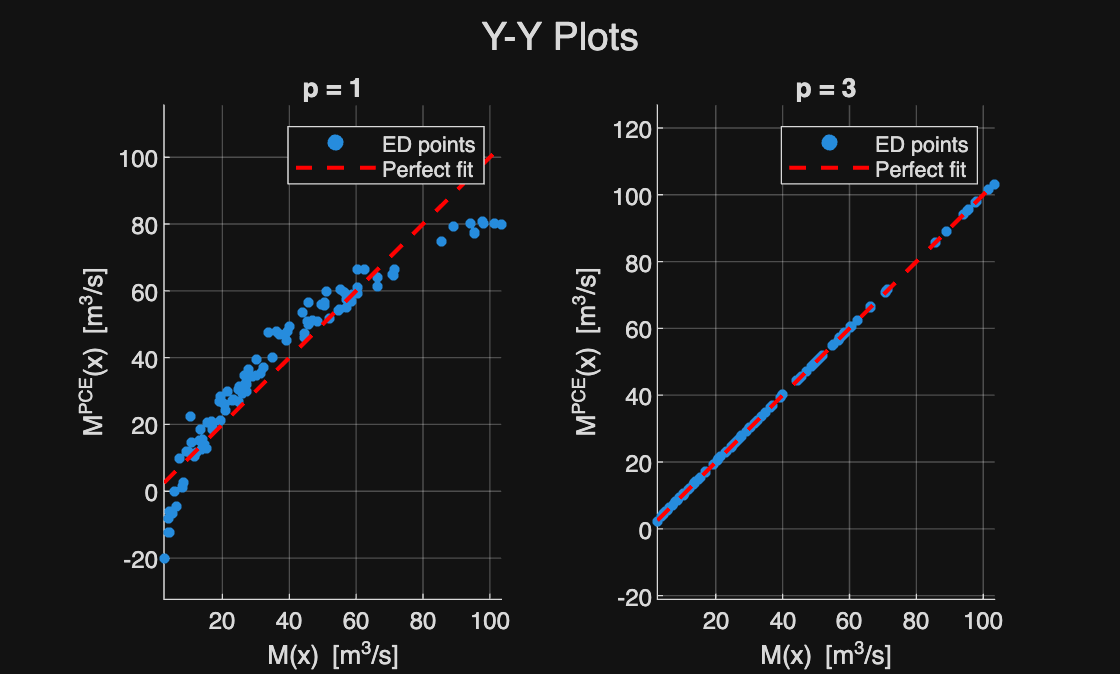

%% 1. Parameters
params(1).type = 'normal';
params(1).mu = 35;
params(1).sigma = 5;

params(2).type = 'uniform';
params(2).a = 8;
params(2).b = 14;

params(3).type = 'uniform';
params(3).a = 0.5;
params(3).b = 2.5;

params(4).type = 'uniform';
params(4).a = 1.0;
params(4).b = 2.5;

params(5).type = 'uniform';
params(5).a = 0.0005;
params(5).b = 0.003;

%% 2. Validation set (created once, reused by all experiments)
n_val = 100000;
[X_val, Y_val] = sampleED(n_val, params, @riverDischarge);

%% 3. Y-Y plots (exp 2.6.1)
n_YY = 100;
p_YY = [1, 3];
exp_YY_plots(params, X_val, Y_val, n_YY, p_YY);

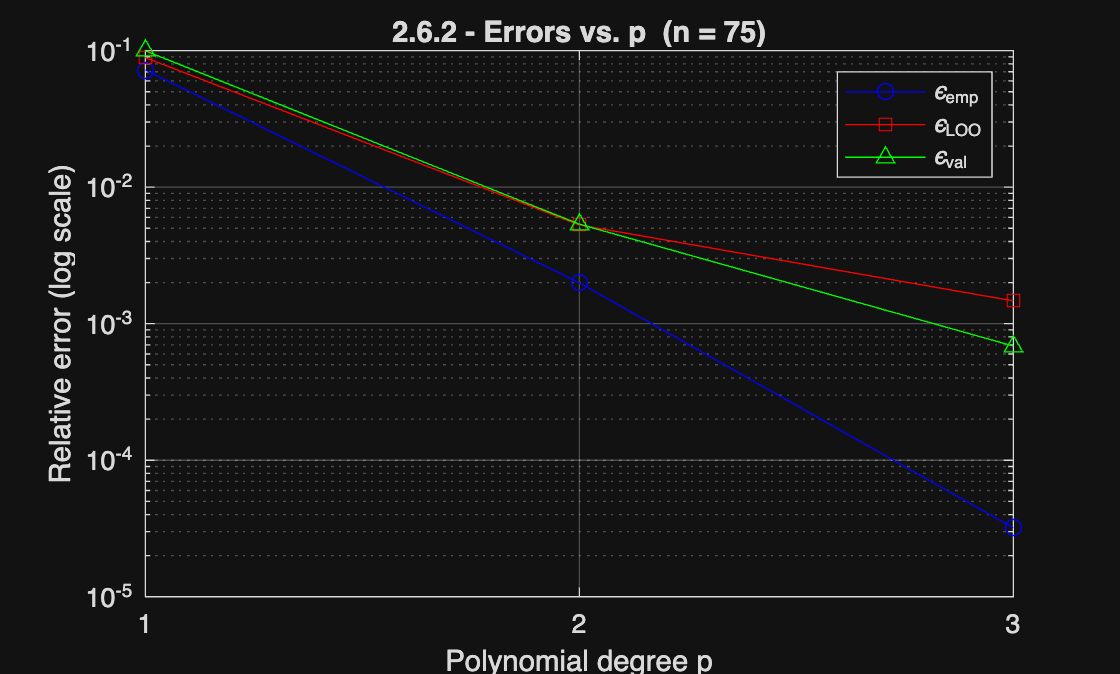

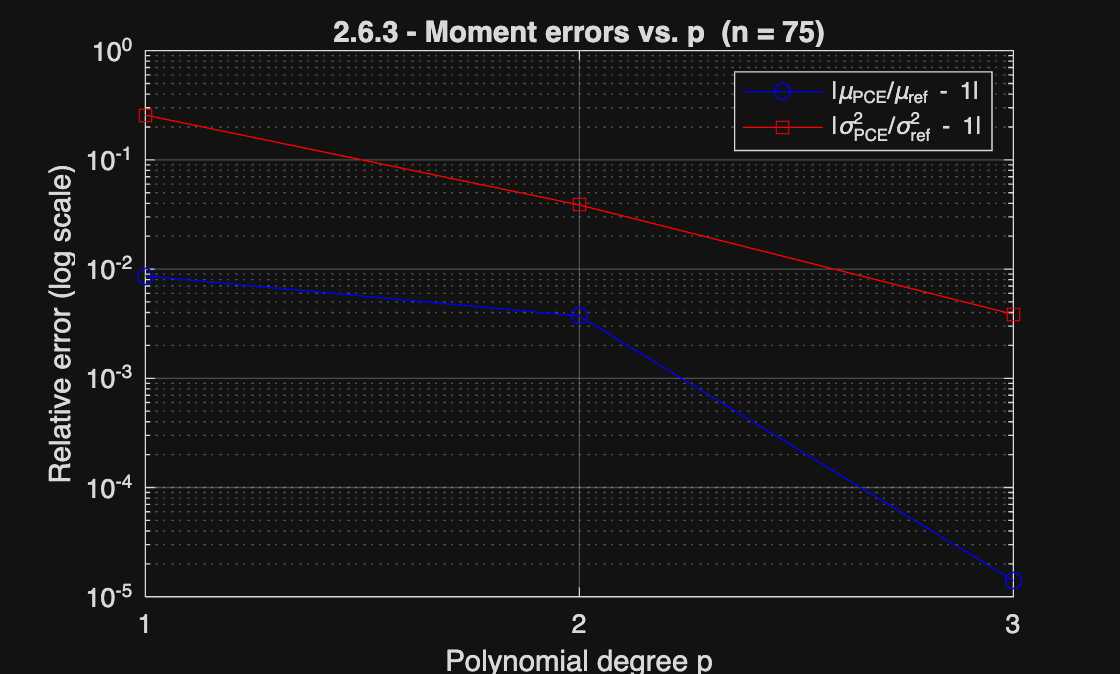


%% 4. Errors and moments vs. p (exp 2.6.2 and 2.6.3)
n_p_sweep = 15 * numel(params);
exp_errors_vs_p(params, X_val, Y_val, n_p_sweep);

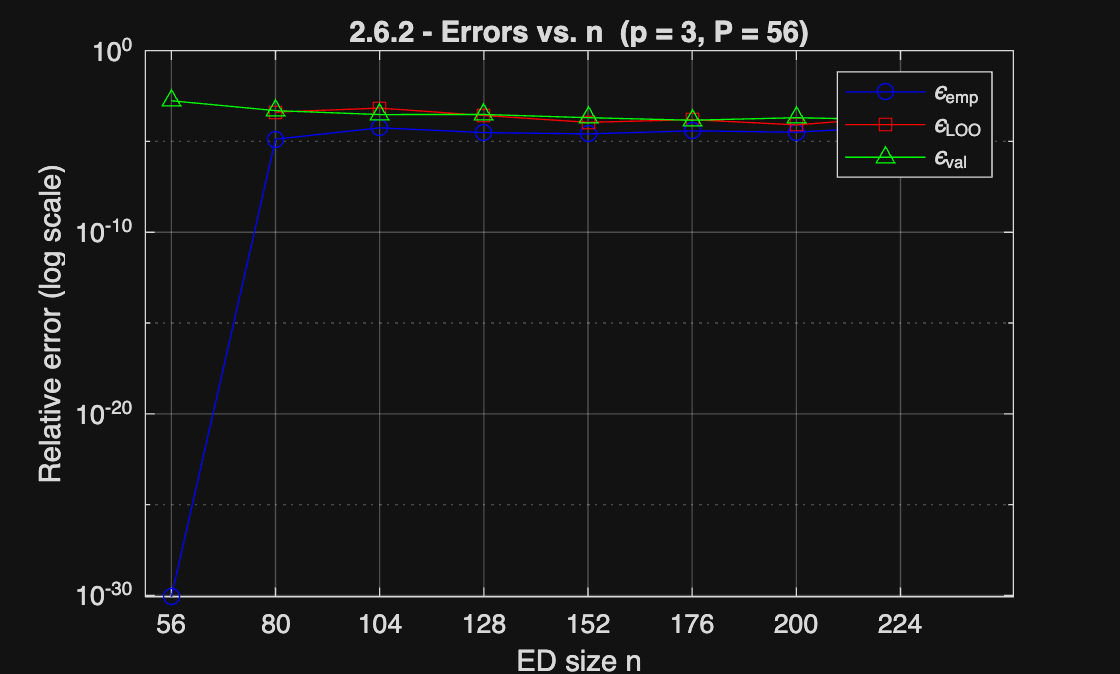

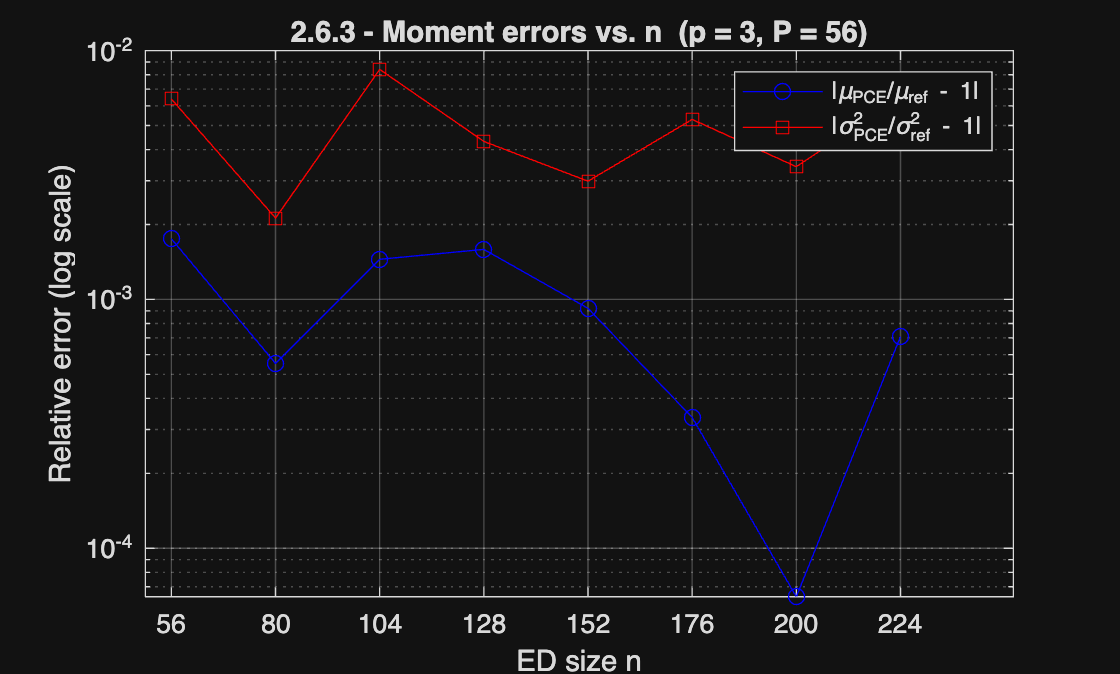


%% 5. Errors and moments vs. n (exp 2.6.2 and 2.6.3)
p_best  = 3;
n_steps = 8;
exp_errors_vs_n(params, X_val, Y_val, p_best, n_steps);